**Time Dissemination Program**

**Background**

White rabbit is a time dissemination protocol which incorporates PTP and SyncE network architecture with subnanosecond accuracy. In a white rabbit network, time is distributed in layers named stratum

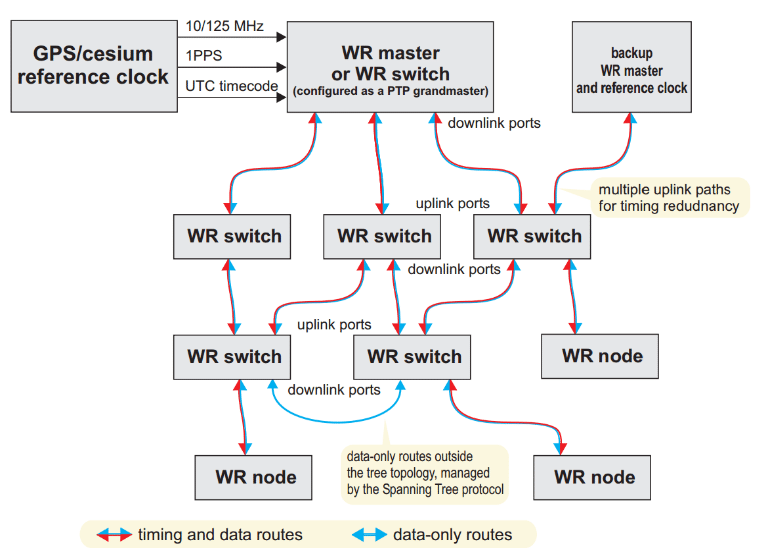

(Tomasz Wlostowski 2010)

A white rabbit grandmaster synchronises with a reference clock (usually an atomic clock) and distribues frequency via SyncE and time via PTP with boundary clocks (denotes in the diagram as WR Switches) which behave as slaves to the grandmaster and masters to clocks on lower stratum levels. Finally the consumers recieve the distributed times (denoted as WR node) from the boundary clocks.

**How is time distributed between a WR master and slave**

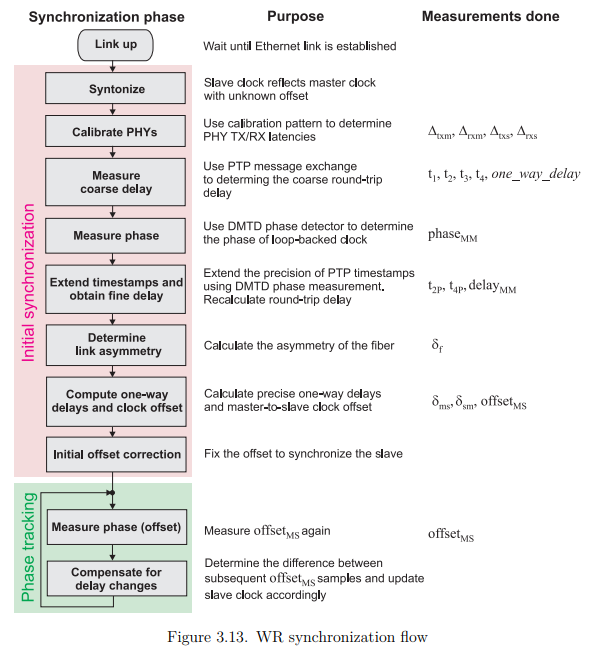

(Tomasz Wlostowski 2010)

The following code will mainly focus on modelling initial synchronisation between a slave and master clock. Later sections will talk about phase tracking.

**Inital Synchronisation**

Before the white rabbit protocols are ran a link must be established between the white rabbit master clock and the slave. White rabbit requires specialised hardware to compose the white rabbit switches for time stamping. The specialised hardware is designed to timestamp packets of data at the physical level which minimises time stamping uncertainty and clock jitter.

Once a link as been established the white rabbit timing process distibutes time to slave clocks

- **SyncE: **SyncE PLL system is used to syntonise the frequency of the master and slave of time.

- **Calibration: **Packets are time stamped at the hardware level which have deterministic latency values $\Delta_1, \Delta_2, \Delta_3, \Delta_4$. These latency values will be taken into account when considering round-way trips of packets.

- **PTP:** A PTP message chain synchronises clock time.

- **Correction: **The master and slave have the same frequency but are out of phase by $\phi$which will be determined by a Digital Dual Mixer Time Difference (DDMTD) phase detector. The PTP values will be adjusted to account for the phase difference and calculate the offset in time between the slave and master.

**SyncE Simulation**

Synchronous Ethernet (SyncE) is a technology used to disseminate clock frequency. As opposed to standard ethernet which syntonises frequency using free oscillator, SyncE uses Phase-Locked Loops (PLL) to lock oscillators to the required frequency. White rabbit uses a heirarchical SyncE network with PLL oscillators distributing frequency to client clocks below them.

A Phase-Locked Loop attempts to match the frequency of the slave with the master by correcting any deviation from the master frequency. A basic PLL have the following modules:

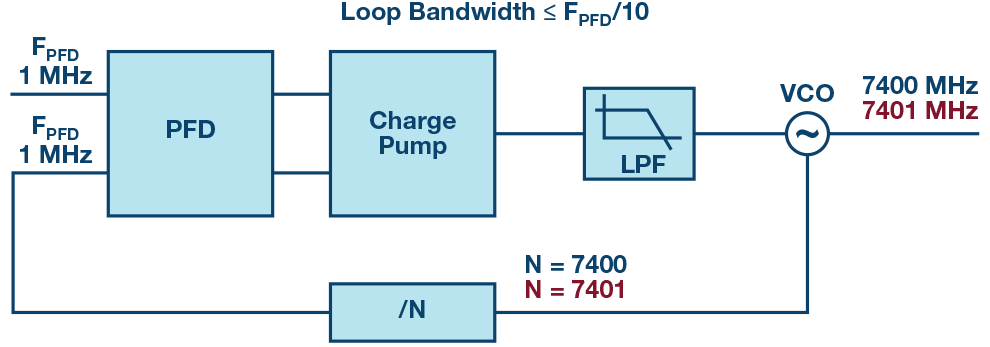

(Ian Colins 2018)

- The master $f_M$ and slave frequency $f_S$ are sent into a phase detector. The error between the frequencies is measures as $f_{error}=f_{S}-f_{M}$.

- A charge pump injects a phase $\phi_{corr}$ to correct the frequency of the slave and match it with the master.

- The low pass filter reduces the noise and jitter frequencies $f_M, \ f_S$.

- The VXCO is the slave oscillator that adjusted by the $\phi_{corr}$ to match closely with the master frequency.

- The new freqency is then passed through the phase detector again in a feedback loop.

The PLL system will allow a slave to match the frequency of the master with some fixed offset phase $f_{offset}$.

Below is a simulation of a PLL system using the *Clock_Simulator.m.*

Refer to *SyncE_Simulator.m* to see how the simulation mimics a PLL system.

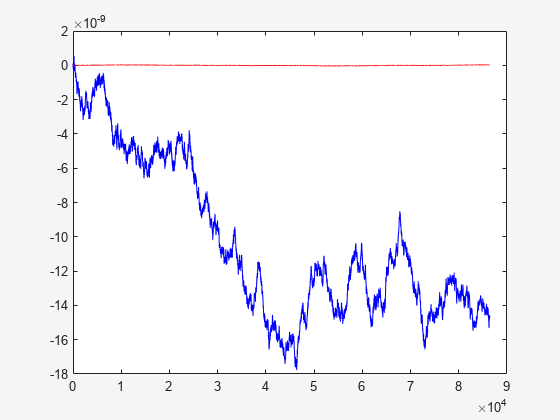

clear

N=86400;
t=1;

diff_master=Diffusion_Coefficient_Estimator((10^-13)^2,(10^-15)^2,1,10^3,0);
diff_slave=Diffusion_Coefficient_Estimator((5*10^-11)^2,(10^-12)^2,1,10^3,0);

X0_master=[0,0,10^-22];
X0_slave=[0,0,10^-13];
P=[0 1 ; 0 1];

[~,MasterFreq,SlaveFreq]=SyncE_Simulator(N,t,X0_master,diff_master,[0,0,0],X0_slave,diff_slave,[0,0,0],0.90,0.5,P);

for i=1:N/t+1
    plot(1:i,MasterFreq(1:i),'b')
    hold on
    plot(1:i,SlaveFreq(1:i),'r')
    hold off

    ylabel('Frequency Deviation / Hz')
    xlabel('time / s')

    legend('master clock (Atomic)', 'slave clock with PLL (VCXO)')

    drawnow
end

Notice that there exists some offset $f_{offset}$. White rabbit correct for the offset using DDMTD module later on.

**PTP & White Rabbit Simulation**

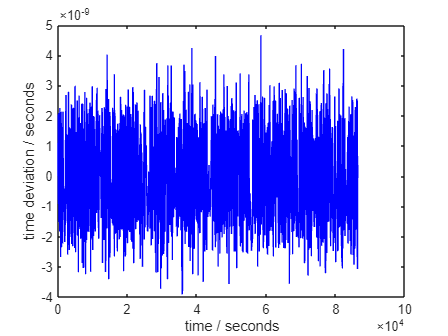

clear;

N=86400;
t=1;

% Master Clock time and frequency.

diff_master=Diffusion_Coefficient_Estimator(10^-26,10^-30,1,10^5,0);
[master_time,master_freq,~]=Clock_Simulator(N,t,[0,0,10^-22],diff_master,[0,0,0]);

% slave clock

slave_clock=[0,0,10^-13,2.5*10^-21,1,10^-24,10^3,0,0,0];

% No of Boundary clocks.

[slave_time,slave_freq]=White_Rabbit_Simulator(N,t,master_time,master_freq,slave_clock,0.1,0.9,20,1000,0.9*3*10^8,[0.99 , 0.01 ; 0.1 , 0.9]);

plot(1:N/t+1,slave_time,'b')

xlabel('time / seconds')
ylabel('time deviation / seconds')

**Multiple Bondary Clocks**

When modelling n clocks in a network we shall consider each clock a node and each uplink and downlink connection will be denoted by a $n \times n$ logical matrix. For simplicity each link between nodes is an uplink and downlink connection (so the logical matrix is symmetric).

% Each element in the set is a node in the network.
% Each cell holds information on tthe stratum level and the type of clock of that node.

Clocks={{0,'Caesium Clock'}, {1,'VCXO Clock'}, {1,'CSAC Clock'}};
Logic_Matrix=[0,1,1;1,0,0;1,0,0]

for i=1:3
    for j=1:i
        if Logic_Matrix(i,j)==1
            for k=1:3
                [Master_Clock,Slave_Clock]=Clock_Type(Clocks{i},Clocks{j});
            end
        end 
    end
end